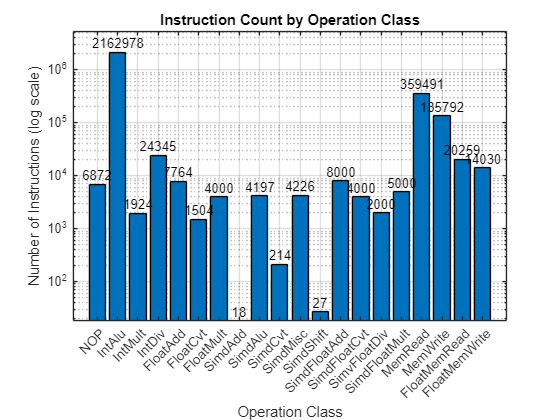

% Data extracted from the CSV file
op_class = {'NOP', 'IntAlu', 'IntMult', 'IntDiv', 'FloatAdd', ...
            'FloatCvt', 'FloatMult', 'SimdAdd', 'SimdAlu', 'SimdCvt', ...
            'SimdMisc', 'SimdShift', 'SimdFloatAdd', 'SimdFloatCvt', 'SimvFloatDiv', ...
            'SimdFloatMult', 'MemRead', 'MemWrite', 'FloatMemRead', 'FloatMemWrite'};
instruction_count = [6872, 2162978, 1924, 24345, 7764, ...
                     1504, 4000, 18, 4197, 214, ...
                     4226, 27, 8000, 4000, 2000, ...
                     5000, 359491, 135792, 20259, 14030];

% Remove entries with zero instruction count
non_zero_indices = instruction_count > 0;
op_class = op_class(non_zero_indices);
instruction_count = instruction_count(non_zero_indices);

% Plot the bar chart
figure;
bar_handle = bar(instruction_count);
set(gca, 'YScale', 'log'); % Set Y-axis to logarithmic scale
set(gca, 'XTick', 1:length(op_class), 'XTickLabel', op_class, 'XTickLabelRotation', 45); % Fix X-axis alignment

ylabel('Number of Instructions (log scale)');
xlabel('Operation Class');
title('Instruction Count by Operation Class');
% Set Y-axis limit to a higher value
ylim([0 max(instruction_count) * 2.5]);  % Increase the upper limit by 10%
% Add counts on top of each bar
xtips = bar_handle.XEndPoints; % Get X positions of the bars
ytips = bar_handle.YEndPoints; % Get Y positions of the bars
labels = string(instruction_count);
text(xtips, ytips * 1.05, labels, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom'); % Adjust position

% Adjust the figure for better spacing
grid on;